# Parametric Optimization of a MEMS resonator (TS4) using MPC

In this example, we tune the drive and sense vibration modes of a MEMS gyroscope prototype (named Test Structure #, TS# in short) modelled using MPC and using parametric optimization (`fmincon`). A similar structure to TS4 has been studied in:

- J. Marconi, G. Bonaccorsi, D. Giannini, L. Falorni and F. Braghin, "Exploiting Nonlinearities for Frequency-Matched MEMS Gyroscopes Tuning," *2021 IEEE International Symposium on Inertial Sensors and Systems (INERTIAL)*, Kailua-Kona, HI, USA, 2021, pp. 1-4, [https://doi.org/10.1109/INERTIAL51137.2021.9430478](https://doi.org/10.1109/INERTIAL51137.2021.9430478) 

clear; close all; clc

*Class path:* `"../src/misc/MultiPointConstraint.m"`

For a tutorial on the `MultiPointConstraint` class, refer to "`../examples/Mechanical/1D/mpc/demo_mpc.mlx`"

## Model definition (example)

Use the below parameters to change the geometry of the structure. Below, find an example with some random parameters:

p(1) =  20; % delta length (drive beams)
p(2) = -10; % delta length (sense beams)
p(3) = 1;   % delta width (drive beams)
p(4) = 1;   % delta width (sense beams)
p(5) = 0;   % delta width (sense beam connections)

The drive beam shapes are modified from straight lines into a composition of harmonics. Considering for simplicity a beam aligned with the x-axis, the final coordinates become


$$y=y_o +\sum_{k=1}^5 H_k \;\sin \left(\frac{k\pi }{L}x\right)$$


being $y_o$ the original y-coordinates of the beam.

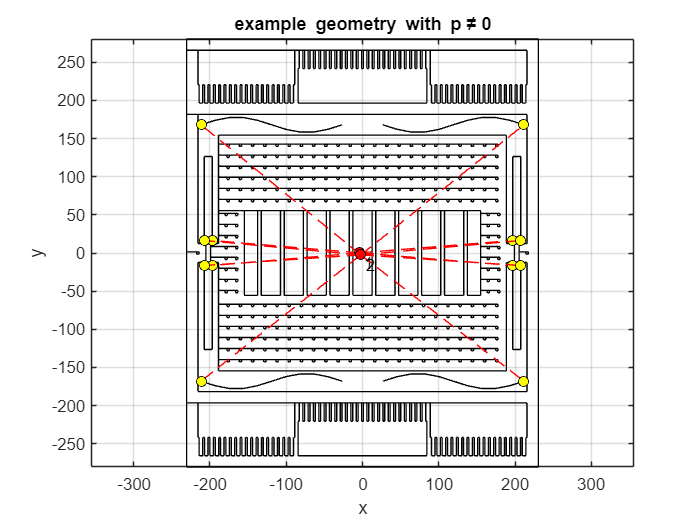

p(6:10)  = [0  10 0 0 0];   % first 5 harmonics for the two TOP drive beams
p(11:15) = [0 -10 0 0 0];   % first 5 harmonics for the two BOTTOM drive beams

obj = mems_ts4_model_param(p);
figure
obj.mpc_plot
title('example geometry with p\neq0')

## Parametric optimization

As often required in MEMS resonators, here we tune the structural modes (drive and sense) to specific target frequencies using `fmincon`.

In this example, we also test the mode-veering tracking. This allows us to switch drive and sense modes, originally the 1st and 2nd modes for p=0, respectively.

	 ceq: 0.00896401 0.0138748
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    1.387e-02    0.000e+00	 ceq: 0.00223994 0.00356298
    1       2    0.000000e+00    3.563e-03    0.000e+00    1.849e-01


	 ceq: 0.000563435 0.000907849
    2       3    0.000000e+00    9.078e-04    0.000e+00    9.316e-02	 ceq: 0.000142056 0.000230325
    3       4    0.000000e+00    2.303e-04    0.000e+00    4.695e-02	 ceq: 3.58469e-05 5.8301e-05	 ceq: 8.01646e-05 0.000130044
    4       6    0.000000e+00    1.300e-04    0.000e+00    1.182e-02	 ceq: 2.02323e-05 3.28983e-05	 ceq: 4.52393e-05 7.34176e-05
    5       8    0.000000e+00    7.342e-05    0.000e+00    8.884e-03	 ceq: 1.14193e-05 1.85648e-05	 ceq: 2.55306e-05 4.14455e-05
    6      10    0.000000e+00    4.145e-05    0.000e+00    6.676e-03	 ceq: 6.44523e-06 1.04766e-05	 ceq: 1.44084e-05 2.33953e-05
    7      12    0.000000e+00    2.340e-05    0.000e+00    5.017e-03	 ceq: 3.63763e-06 5.91238e-06	 ceq: 8.13162e-06 1.32058e-05
    8      14    0.000000e+00    1.321e-05    0.000e+00    3.770e-03	 ceq: 2.0531e-06 3.33668e-06	 ceq: 4.58923e-06 7.4539e-06
    9      16    0.000000e+00    7.454e-06    0.000e+00    2.832e-03	 ceq: 1.15874e-06 1.88309e-06	

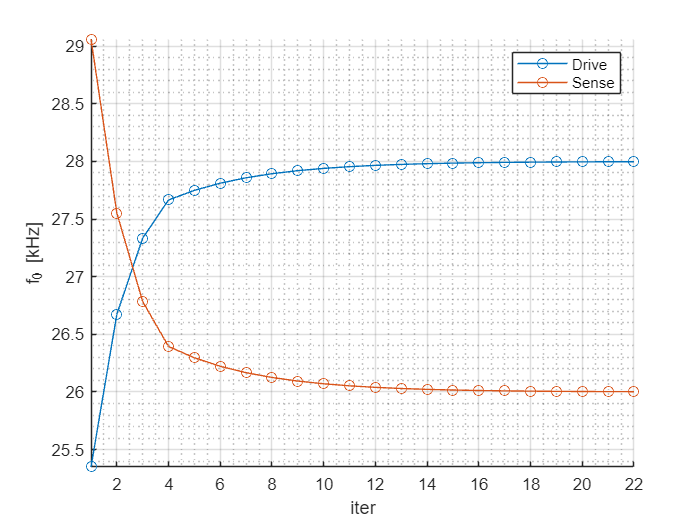

% Initial conditions x = [p]
x0 = p*0;

% Linear constraints
A = []; b = [];
Aeq = []; beq = [];

% Bounds
lb = -[25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];
ub =  [25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];

args.sys_fun = @(p) mems_ts4_model_param(p); % function that evaluates the model at p

args.imod = [1 2];              % mode shape to track
args.f_target = [28 26]*1e3;    % [Hz] mode shape frequency

args.desired_percent_error = 0.01; % allowed percent frequency error 

t0=tic;
[xsol,fval,history] = runfmincon(x0, A, b, Aeq, beq, lb, ub, args);

topt = toc(t0);
fprintf(' Optimization time: %d min %.0f s\n\n', floor(topt/60), rem(topt,60))

 Optimization time: 0 min 36 s



## Optimization results

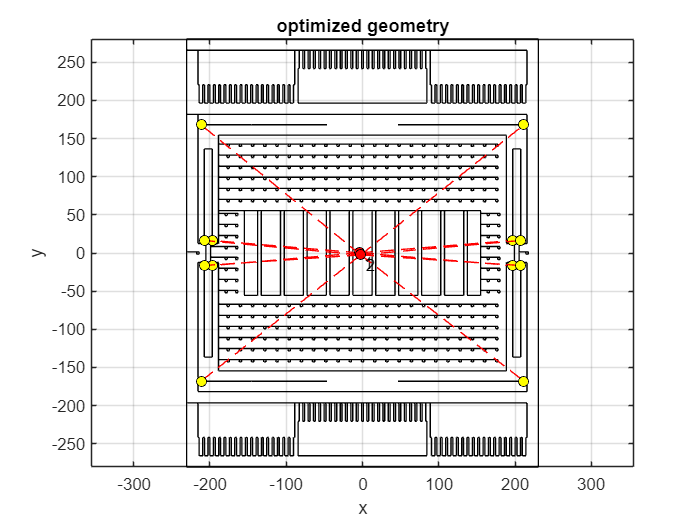

obj = mems_ts4_model_param(xsol);
figure
obj.mpc_plot
title('optimized geometry')

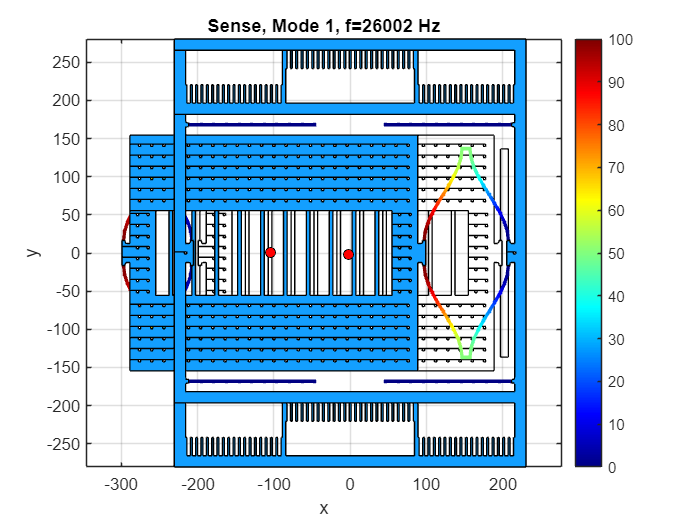

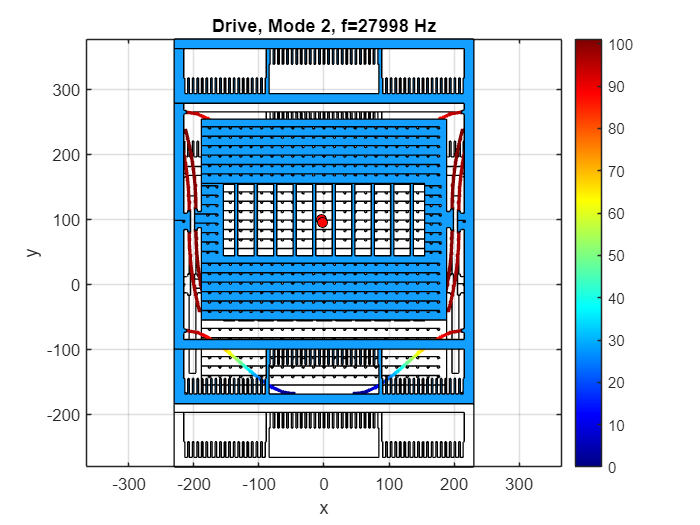

u0   = zeros( obj.Mesh.nDOFs, 1);
Kmpc = obj.tangent_stiffness_and_force(u0);
Mmpc = obj.mass_matrix;

% Eigenvalue problem                                               
n_VMs = 7; % first n_VMs modes with lowest frequency calculated 
[Phi1,om2] = eigs(Kmpc, Mmpc, n_VMs, 'SM');
[om, ind] = sort(sqrt(diag(om2)));
f0 = om/2/pi;

scale = 100;
for imod = sort(history.imod(end,:))
    figure
    obj.mpc_plot(Phi1(:,imod),scale)
    u_mass = Phi1(end-5:end-3,imod);
    [~,ind] = max(abs(u_mass));
    if ind==1
        t = 'Sense, ';
    elseif ind==2
        t = 'Drive, ';
    else
        t = '';
    end

    title(sprintf('%sMode %d, f=%.0f Hz', t, imod, f0(imod)))
end